clear all, close all, clc;

# Cleaning Data Using FFT Transform


$$\pmatrix{ | \cr f \cr | } \quad \overset{FFT}{\rightarrow} \quad \pmatrix{ | \cr \hat f \cr | } 
\quad \underset{| \hat f|^2 < 100 }{\overset{Filter}{\rightarrow}} \quad \pmatrix { | \cr \hat{ f}_{filt} \cr | }  \quad 
\overset{iFFT}{\rightarrow} \quad \pmatrix{| \cr f_{filt} \cr |}$$


**1. Generate Data**

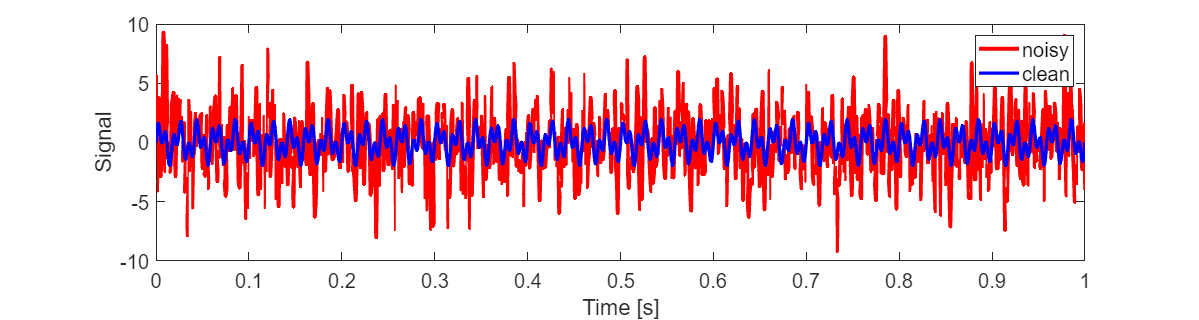

Fs = 1000; %[hz]
dt = 1/Fs;
t = 0:dt:1;
fclean = sin(2*pi*50*t) + sin(2*pi*120*t);
f = fclean + 2.5*randn(size(t));
figure("Position",[0 0 1500 400])

plot(t, f, 'r', 'LineWidth', 3.0, 'DisplayName', 'noisy'), hold on
plot(t, fclean, 'b', 'LineWidth', 2.5, 'DisplayName', 'clean')
xlabel('Time [s]', "FontSize", 15)
ylabel('Signal', "FontSize", 15)
set(gca, 'FontSize', 15)
legend('FontSize',15)

% set(gcf, 'Visible', 'on');

**2. Compute FFT**

n = length(t);
fhat = fft(f, n);
PSD = fhat.*conj(fhat) / n;
freq = Fs/n*(0:n);
L = 1:floor(n/2);


**3. Noise FIltering**

inicies = PSD > 100;
PSDclean = PSD.*inicies;
fhat = inicies.*fhat;
ffilt = ifft(fhat);

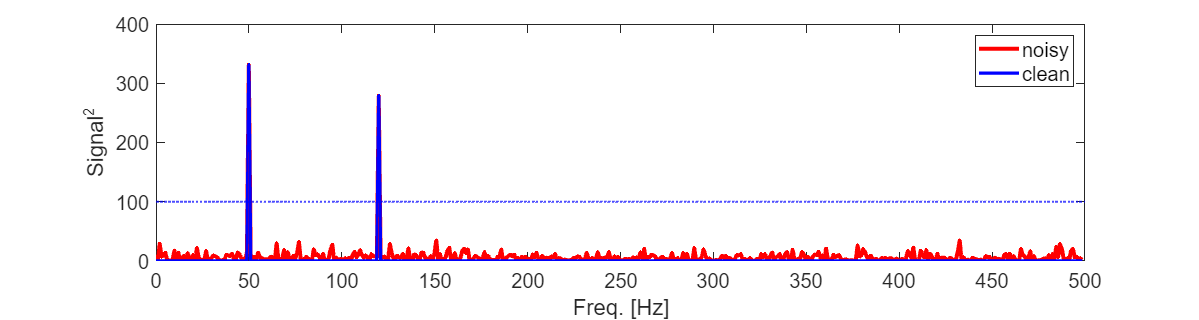


figure("Position",[0 0 1500 400])

plot(freq(L), PSD(L), 'r', 'LineWidth', 3, 'DisplayName','noisy'), hold on
plot(freq(L), PSDclean(L), 'b-', 'LineWidth', 2.5, 'DisplayName', 'clean')
yline(100, 'b:', 'LineWidth',1.5)
lg = legend('FontSize',15);
lg.String = lg.String(1:2);
xlabel('Freq. [Hz]', "FontSize", 15)
ylabel('Signal^2', "FontSize", 15)
set(gca, 'FontSize', 15)

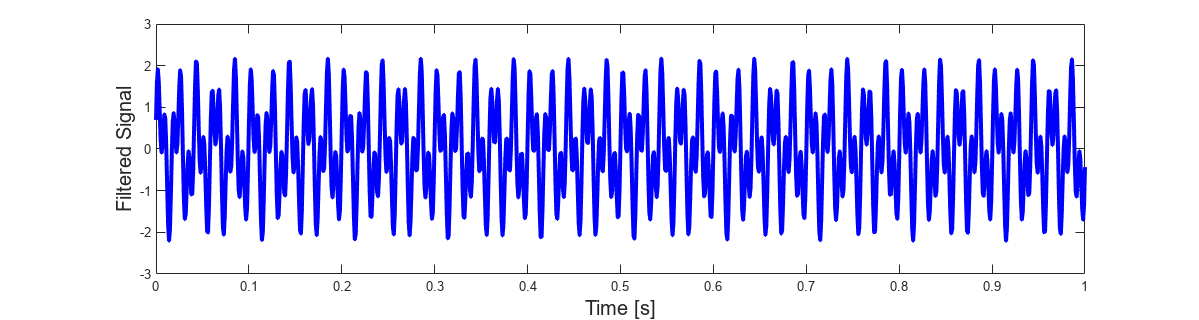

figure("Position",[0 0 1500 400])

plot(t, ffilt, 'b-', 'LineWidth', 3)
xlabel('Time [s]', "FontSize", 15)
ylabel('Filtered Signal', 'FontSize', 15)